# ROS Tutorial

ROS network comprises different parts of a robot system (such as a planner or a camera interface) that communicate over ROS. The network can be distributed over several machines. 

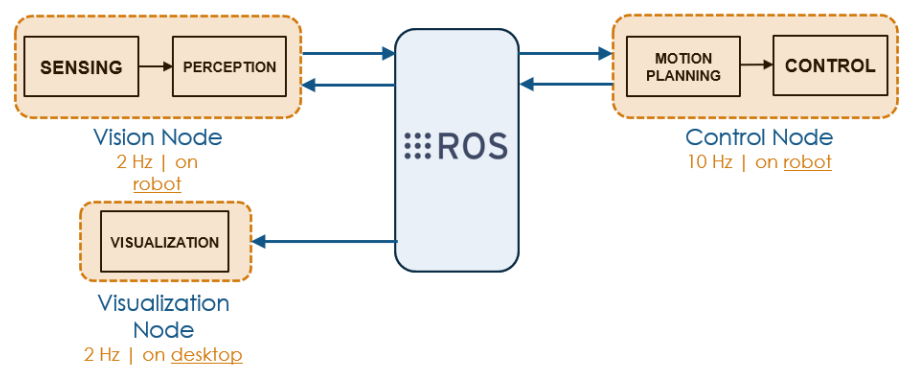

## ROS Master

ROS Master (only for ROS1): it coordinates the different parts of a ROS network. It is identified by a Master URI (Uniform Resource Identifier) that specifies the hostname or IP address of the machine where the master is running.

### How to initialize/shut down a ROS Master

To initialize a ROS Master node: 

- *>> rosinit*: It creates a ROS Master node. It’s the node of reference for the whole system.

rosinit

To shut down the ROS Master node: 

- >> *rosshutdown*: It closes the Master node and all the processes that depends on that Master

rosshutdown

## Nodes & Topics

In ROS, each complex task can be split into simpler problems/subtasks (“Divide and conquer” paradigm). These simple tasks are solved using single purpose programs able to communicate through special channel. We call: 

- **Node:** piece of software (programs) performing a specific subtasks;

- **Topics:** the inter-communication channels among different nodes;

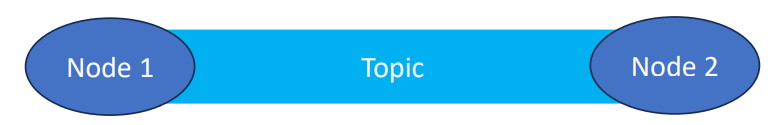

### How to get information

**Nodes** can be explored by typing: 

rosnode list 
rosnode info /node_name 
rosnode ping /node_name

**Topics** can be explored by typing: 

rostopic list 
rostopic info /topic_name 
rostopic type /topic_name 
rostopic echo /topic_name

## Nodes Publishers/Subscribers

Each node in a ROS network can be : 

- A **publisher node** : It sends information to the ROS network by means of a given communication channel ; 

- A **subscriber node** : It receives information from the ROS network by means of a given communication channels ;

-  Both ; 

Nodes can publish on/subscribe to one or several topics (as defined in its code). These nodes are meant to operate at a fine - grained scale ; a robot control system will usually comprise many nodes.  For example, one node controls a laser range -finder, one Node controls the robot's wheel motors, one node performs localization, one node performs path planning, one node provides a graphical view of the system, and so on

Nodes can be publishers **OR** subscribers 

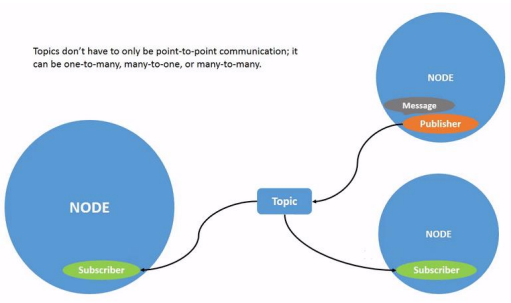

### MATLAB **subscriber syntax**: 

sub = rossubscriber("/topic_name", "DataFormat", "struct")
msg = receive (sub) % It waits to receive a topic from a subscriber

The “struct” format allows to save data in the specified format. 

sub = rossubscriber("/topic_name",@Callback,"DataFormat","struct")

A callback is a user-defined function that is triggered every time the subscriber receives a message and can be used to process the received data avoiding to wait and use “receive”.

### MATLAB **publisher syntax**:

pub = rospublisher("/topic_name", "message_Type","DataFormat", "struct")
msg = rosmessage(pub) % initializes the message variable to be sent
msg.Data = 'my_message' % message to be sent
send(pub,msg) % It sends the message through the publisher

The message is sent to the node that subscribe to that information

## Messages

A message is a Data structures containing fields of predetermined data types. Messages are the primary container for exchanging data in ROS.

To identify its data structure, each message has a message type. For example, sensor data from a laser scanner is typically sent in a message of type sensor_msgs/LaserScan.

Every message type name is a combination of: 

- the name of the package that contains that specific message,

- a forward slash /,

- the type name, typically used to define the purpose of the message type

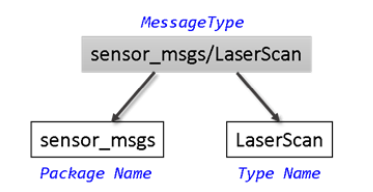

msg = rosmessage("message_type", "DataFormat", "struct")

Message type in ROS:

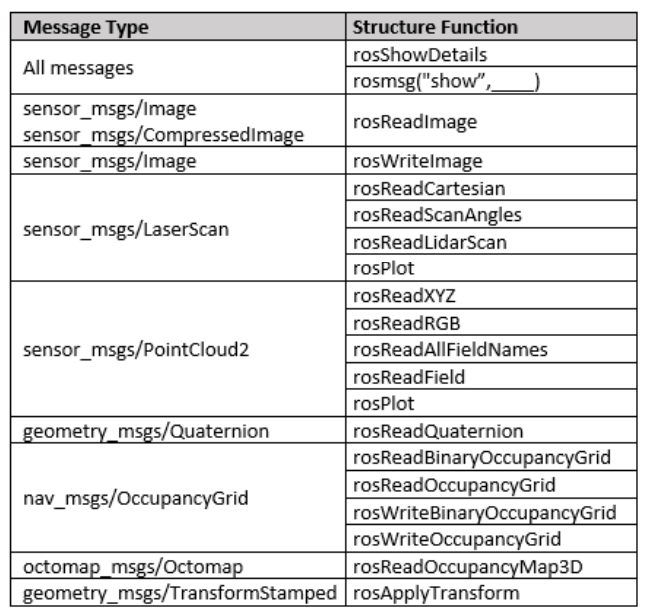

## Communication mechanisms

The primary mechanism for ROS nodes to exchange data is sending and receiving messages. Messages are transmitted on a topic, and each topic has a unique name in the ROS network. 

If a node wants to share information, it uses a publisher to send data to a topic. A node that wants to receive that information uses a subscriber to that same topic. Besides its unique name, each topic also has a message type, which determines the types of messages that are capable of being transmitted under that topic. 

### Publishers & Subscribers

The publisher and subscriber communication has the following characteristics:

- Topics are used for many-to-many communication. Many publishers can send messages to the same topic and many subscribers can receive them.

- Publishers and subscribers are decoupled through topics and can be created and destroyed in any order. A message can be published to a topic even if there are no active subscribers. 

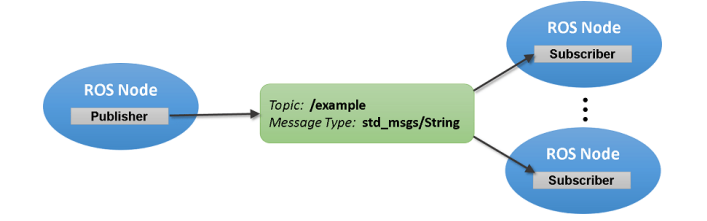

### Services & Actions

There are other communication mechanisms in ROS, which are Services and Actions: 

- **Services** are used to perform one-time tasks in order to obtain a specific result. It is an event-based communication since the tasks need to be requested by a client to a server. Services are used for short-running tasks since they are associated with a timeout. 

For example: • In image processing applications, the client might request for object recognition on one image frame and get the coordinates of the bounding boxes 

- **Actions** are client-server models that are employed when it is required to execute long-running tasks, and the services are not adequate to run those tasks. These long-running tasks can be monitored (receive feedbacks) and cancelled. 

For example:

- In path planning and navigation, it is used to send multiple goals to the mobile robot 

- In manipulation tasks, it is used to provide a sequence of motion to be followed by the manipulator and grasp an object